% Autor: Luis Eduardo Arenas Deseano
% Proyecto: Sistemas Inteligentes
% Descripción: Funcion de Rastringin para Algoritmos geneticos
% Fecha: 1/12/2024

rastrigin

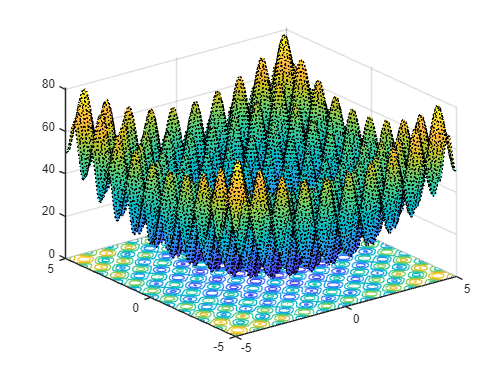

fsurf(@(x,y)reshape(rastriginsfcn([x(:),y(:)]),size(x)),...
    "MeshDensity",100,...
    "ShowContours","on",...
    "LineStyle",":")


rng default % For reproducibility
nvar = 2;
fun = @rastriginsfcn;

ga stopped because the average change in the fitness value is less than options.FunctionTolerance.


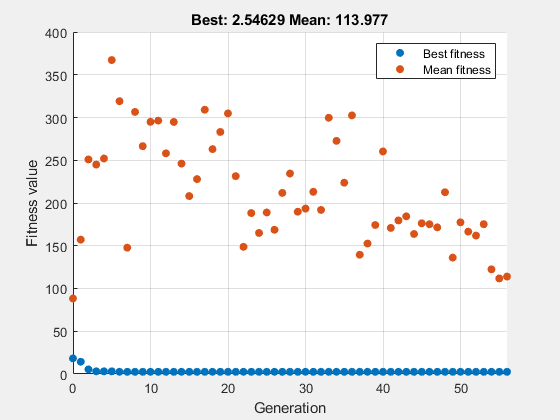

% Set nondefault solver options
options = optimoptions("ga","PlotFcn","gaplotbestf");

% Solve
[solution,objectiveValue] = ga(fun,nvar,[],[],[],[],[],[],[],[],options);


% Clear variables
clearvars options

ga stopped because the average change in the fitness value is less than options.FunctionTolerance.


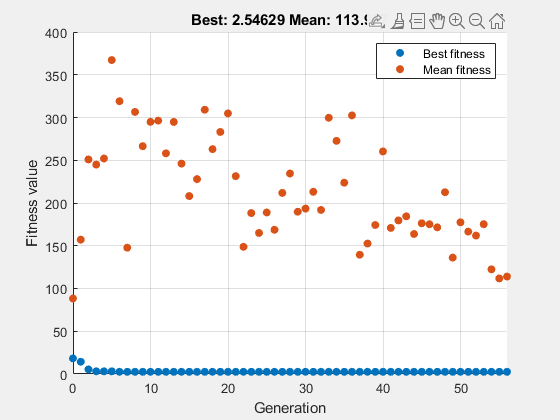

solution =     0.9785    0.9443


objectiveValue = 2.5463

rng default % For reproducibility
options = optimoptions('ga','PlotFcn','gaplotbestf');
[solution,objectiveValue] = ga(@rastriginsfcn,2,...
    [],[],[],[],[],[],[],options)